Vehicle Control Engineering Homework 3 Solution

Author: Huiqian LI (2020310535)

Date: 2020-11-4

 %% Known parameters
 clear,clc
 Ms = 1250;
 Ks = 44000;
 Cs = 4000;
 Mus = 200;
 Kus = 400000;
 Cus = 100;

% State space model
A = [0,1,0,0;-Kus/Mus,-(Cs+Cus)/Mus,Ks/Mus,Cs/Mus;0,-1,0,1;0,Cs/Ms,-Ks/Ms,-Cs/Ms];
B = [0;Ms/Mus;0;-1]/Ms;
B2 = [-1;Cus/Mus;0;0];
C = [-1;Cus/Mus;0;0];
% Controllablity matrix 
Qc = [B,A*B,A*A*B,A*A*A*B];
rank(Qc); % = 4

Since the rank is equal to 4, the system is controllable.

% Design of LQ controller
Q = 1000*eye(4);
R = 0.01;
K = lqr(A,B,Q,R)

K =    79.0773   11.7549   -1.1363  -15.5433


% Calculate the coefficient of the chracteristic polynomial
syms s Ms Ks Cs Mus Kus Cus k_1 k_2 k_3 k_4
A = [0,1,0,0;-Kus/Mus,-(Cs+Cus)/Mus,Ks/Mus,Cs/Mus;0,-1,0,1;0,Cs/Ms,-Ks/Ms,-Cs/Ms];
B = [0;Ms/Mus;0;-1]/Ms;
C = [-1;Cus/Mus;0;0];
K = [k_1,k_2,k_3,k_4]

$$K = \left(\begin{array}{cccc} k_{1} & k_{2} & k_{3} & k_{4} \end{array}\right)$$

rho = collect(det(s*eye(4)-A+B*K))

$$rho = s^{4}+\frac{\mathrm{Ms}\,k_{2}-\mathrm{Mus}\,k_{4}+\mathrm{Cs}\,\mathrm{Ms}+\mathrm{Cs}\,\mathrm{Mus}+\mathrm{Cus}\,\mathrm{Ms}}{\mathrm{Ms}\,\mathrm{Mus}}\,s^{3}+\frac{\mathrm{Ms}\,k_{1}-\mathrm{Cus}\,k_{4}-\mathrm{Ms}\,k_{3}-\mathrm{Mus}\,k_{3}+\mathrm{Cs}\,\mathrm{Cus}+\mathrm{Ks}\,\mathrm{Ms}+\mathrm{Ks}\,\mathrm{Mus}+\mathrm{Kus}\,\mathrm{Ms}}{\mathrm{Ms}\,\mathrm{Mus}}\,s^{2}+\left(-\frac{\mathrm{Cus}\,k_{3}+\mathrm{Kus}\,k_{4}-\mathrm{Cs}\,\mathrm{Kus}-\mathrm{Cus}\,\mathrm{Ks}}{\mathrm{Ms}\,\mathrm{Mus}}\right)\,s-\frac{\mathrm{Kus}\,k_{3}-\mathrm{Ks}\,\mathrm{Kus}}{\mathrm{Ms}\,\mathrm{Mus}}$$

% Alternative parameters-maximum ai
 Ms = 0.8*Ms;
 Ks = 1.2*Ks;
 Cs = 1.2*Cs;
 Mus = 0.8*Mus;
 Kus = 1.2*Kus;
 Cus = 1.2*Cus;

% Alternative parameters-minimum ai
 Ms = 1.2*Ms;
 Ks = 0.8*Ks;
 Cs = 0.8*Cs;
 Mus = 1.2*Mus;
 Kus = 0.8*Kus;
 Cus = 0.8*Cus;

% Calculate coefficients
k_1 = K(1),k_2=K(2),k_3=K(3),k_4=K(4);

k_1 = 79.0773

k_2 = 11.7549

k_3 = -1.1363

a_4 = 1

a_4 = 1

a_3 = (Ms*k_2 - Mus*k_4 + Cs*Ms + Cs*Mus + Cus*Ms)/(Ms*Mus);
a_2 = (Ms*k_1 - Cus*k_4 - Ms*k_3 - Mus*k_3 + Cs*Cus + Ks*Ms + Ks*Mus + Kus*Ms)/(Ms*Mus);
a_1 =  - (Cus*k_3 + Kus*k_4 - Cs*Kus - Cus*Ks)/(Ms*Mus);
a_0 = - (Kus*k_3 - Ks*Kus)/(Ms*Mus);
a_min = [7.040189391493771e+04,6.443505908111761e+03,2.257225202504221e+03,23.774176293337180];
a_max = [1.584034090468879e+05,1.448623063460117e+04,3.386914128820260e+03,35.639011552004620];

% Kharitonov's theorem
syms s
K1 = a_min(1)+a_min(2)*s+a_max(3)*s^2+a_max(4)*s^3+s^4;
K2 = a_min(1)+a_max(2)*s+a_max(3)*s^2+a_min(4)*s^3+s^4;
K3 = a_max(1)+a_min(2)*s+a_min(3)*s^2+a_max(4)*s^3+s^4;
K4 = a_max(1)+a_max(2)*s+a_min(3)*s^2+a_min(4)*s^3+s^4;
% Solve roots of the equations
root1 = solve(K1,s)

$$root1 = \begin{array}{l} \left(\begin{array}{c} \mathrm{root}\left(\sigma_{1},z,1\right)\\ \mathrm{root}\left(\sigma_{1},z,2\right)\\ \mathrm{root}\left(\sigma_{1},z,3\right)\\ \mathrm{root}\left(\sigma_{1},z,4\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=z^{4}+\frac{2507872486647825\,z^{3}}{70368744177664}+\frac{3723951466916697\,z^{2}}{1099511627776}+\frac{7084709669612235\,z}{1099511627776}+\frac{2418990655528951}{34359738368} \end{array}$$

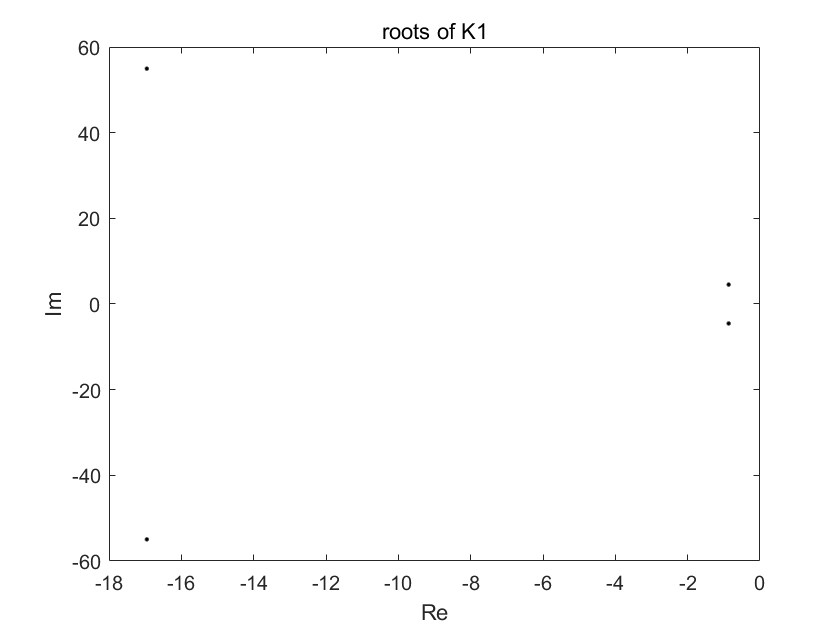

figure(1)
plot(root1,'.k')
xlabel('Re'),ylabel('Im'),title('roots of K1')

root2 = solve(K2,s)

$$root2 = \begin{array}{l} \left(\begin{array}{c} \mathrm{root}\left(\sigma_{1},z,1\right)\\ \mathrm{root}\left(\sigma_{1},z,2\right)\\ \mathrm{root}\left(\sigma_{1},z,3\right)\\ \mathrm{root}\left(\sigma_{1},z,4\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=z^{4}+\frac{6691835718482113\,z^{3}}{281474976710656}+\frac{3723951466916697\,z^{2}}{1099511627776}+\frac{7963889512694445\,z}{549755813888}+\frac{2418990655528951}{34359738368} \end{array}$$

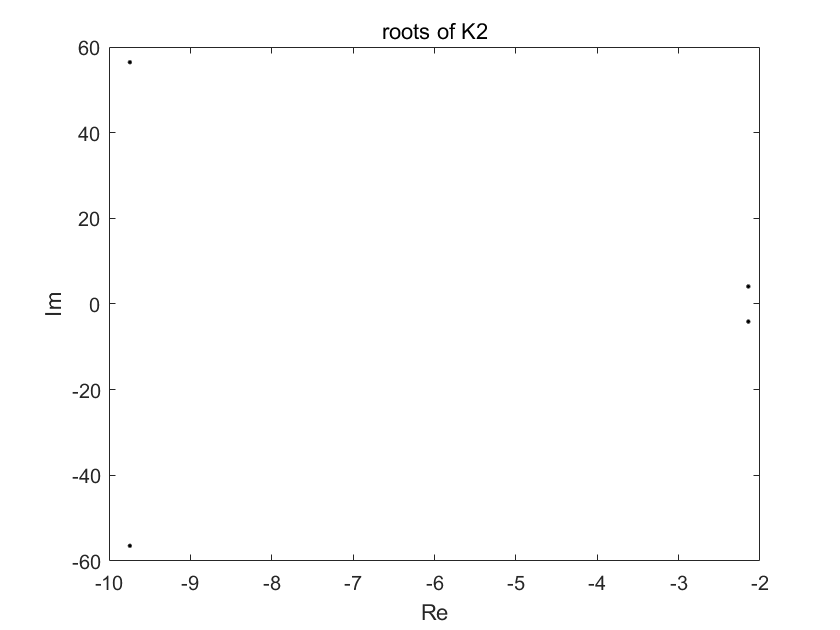

figure(2)
plot(root2,'.k')
xlabel('Re'),ylabel('Im'),title('roots of K2')

root3 = solve(K3,s)

$$root3 = \begin{array}{l} \left(\begin{array}{c} \mathrm{root}\left(\sigma_{1},z,1\right)\\ \mathrm{root}\left(\sigma_{1},z,2\right)\\ \mathrm{root}\left(\sigma_{1},z,3\right)\\ \mathrm{root}\left(\sigma_{1},z,4\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=z^{4}+\frac{2507872486647825\,z^{3}}{70368744177664}+\frac{4963690713324855\,z^{2}}{2199023255552}+\frac{7084709669612235\,z}{1099511627776}+\frac{340168730715647}{2147483648} \end{array}$$

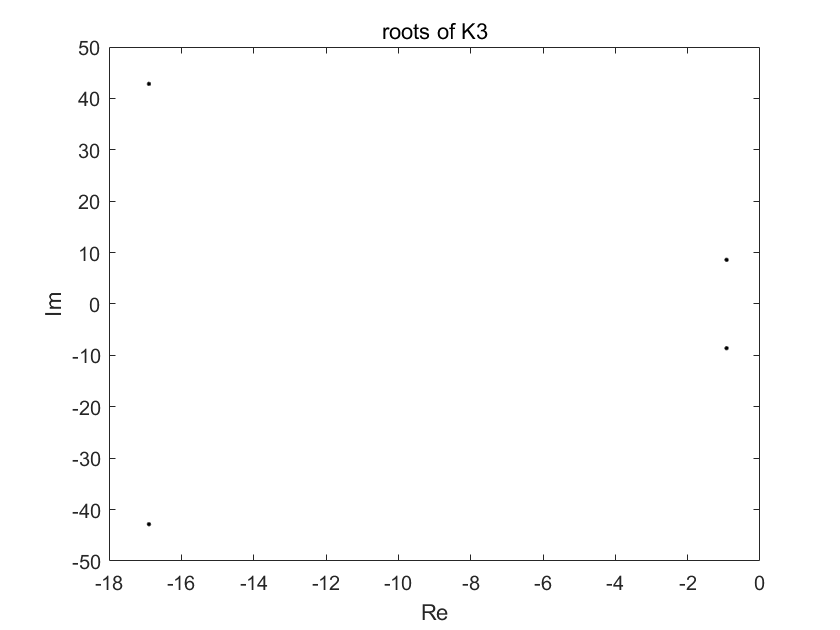

figure(3)
plot(root3,'.k')
xlabel('Re'),ylabel('Im'),title('roots of K3')

root4 = solve(K4,s)

$$root4 = \begin{array}{l} \left(\begin{array}{c} \mathrm{root}\left(\sigma_{1},z,1\right)\\ \mathrm{root}\left(\sigma_{1},z,2\right)\\ \mathrm{root}\left(\sigma_{1},z,3\right)\\ \mathrm{root}\left(\sigma_{1},z,4\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=z^{4}+\frac{6691835718482113\,z^{3}}{281474976710656}+\frac{4963690713324855\,z^{2}}{2199023255552}+\frac{7963889512694445\,z}{549755813888}+\frac{340168730715647}{2147483648} \end{array}$$

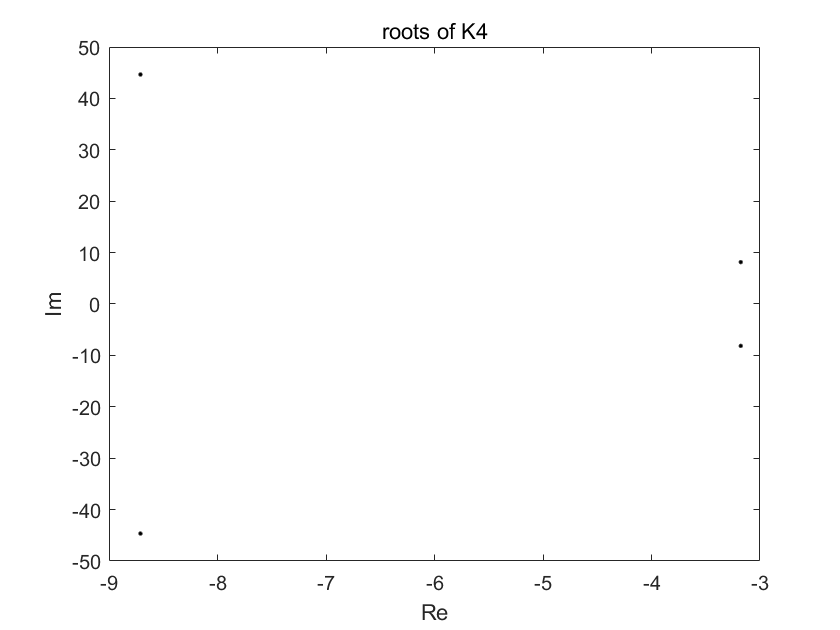

figure(4)
plot(root4,'.k')
xlabel('Re'),ylabel('Im'),title('roots of K4')

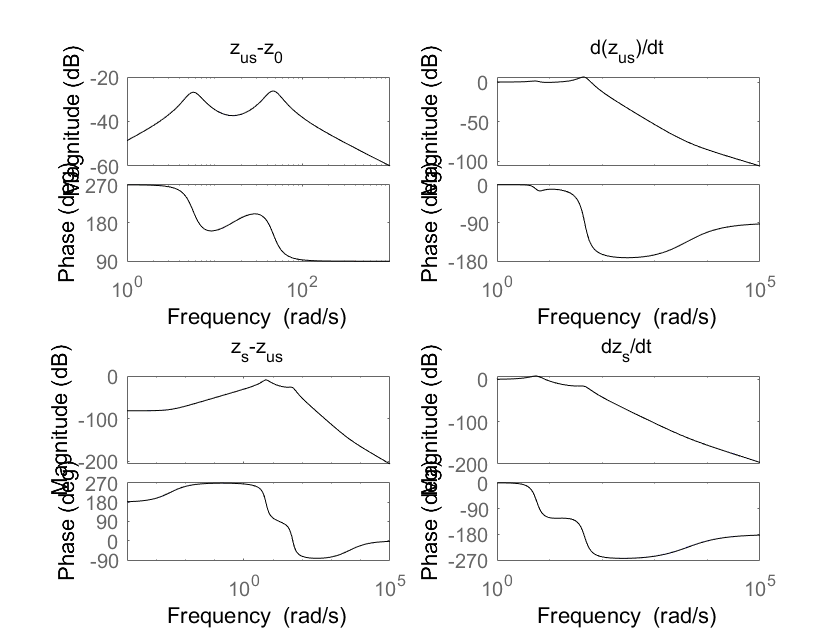

% Plot Bode graph
plot_bode_graph(A,B,B2,Q,R,'Q11')

function plot_bode_graph(A,B1,B2,Q,R,variable)
    K = {[],[],[],[]};
    if variable == "Q11"
        for i = 2:5
           Q(1,1) = 10^i;
           K{i-1} = lqr(A,B1,Q,R);
        end
    elseif variable == "Q22"
        for i = 2:5
           Q(2,2) = 10^i;
           K{i-1} = lqr(A,B1,Q,R);
        end
    elseif variable == "Q33"
        for i = 2:5
           Q(3,3) = 10^i;
           K{i-1} = lqr(A,B1,Q,R);
        end 
    elseif variable == "Q44"
        for i = 2:5
           Q(4,4) = 10^i;
           K{i-1} = lqr(A,B1,Q,R);
        end
    elseif variable == "R"
        for i = 0:3
           R = 10^(-i);
           K{i+1} = lqr(A,B1,Q,R);
        end 
    end
    title_set = ["z_{us}-z_0","d(z_{us})/dt","z_s-z_{us}","dz_s/dt"];
    color_set = ["r","g","b","k"];
    figure()
    for i = 1:4
        subplot(2,2,i)
        for j = 1:size(K,2)
            sys = ss(A-B1*K{j},B2,eye(4),zeros(4,1));
            bode(sys(i),color_set(j))
            hold on 
        end
        title(title_set(i)) 
    end
    
end